clc;
clear all;
close all;
pause('off');

# **Adaptive Controls**

# **Project Part 1 (Motor Control)**

# **Japnit Sethi**

**Objective:** The purpose of the project is to design a model reference adaptive controller for a DC motor drive, which accounts for the presence of an unknown deadzone in the power electronincs, so that the approximate velocity tracking may be achieved without knowledge of motor, load or deadzone parameters.

Dynamics of the **brush-commutated permanent-magent DC motor** turning an inertial load are described by:

$J\ldotp \frac{d}{\mathrm{d}t}\omega \;=-B\ldotp \omega \left(t\right)\;+K\ldotp i\left(t\right)$                             -   **(1)**

$L\ldotp \frac{d}{\mathrm{d}t}i\;=-K\ldotp \omega \left(t\right)\;-R\ldotp i\left(t\right)+v\left(t\right)$                    -   **(2)**

where, $\omega \left(t\right)$ is the mechanical state variable (angular velocity) **[INPUT]**

            $i\left(t\right)$ is the electrical state variable (armature current)

            $v\left(t\right)$ is the input to the motor terminals (armature voltage) [**OUTPUT**]

            J (inertia) and B (viscious friction) are** unknown constant mechanical parameters**

            L (armature inductance), R (armature Resistance) and K (motor constant) are **unknown constant electrical parameters**

Each of the unknowns J, B, L, R and K are known to be **strictly positive**

The signal $v_d \left(t\right)$ is designed such that if v(t) = $v_d \left(t\right)$, the output velocity $\omega \left(t\right)$ tracks a desired velocity signal $\omega_d \left(t\right)$ provided as the output of a reference model. The **only measurement of the plant response available to the control system is the output **$\omega \left(t\right)$ (i.e. $i\left(t\right)\;\mathrm{and}\;v\left(t\right)$are not available). The desired output is specified to be:


$$\omega_d \left(t\right)=10\cdot \mathrm{sin}\left(2t\right)$$


but the choice of reference model (and corresponding reference signal $r\left(t\right)$) is not specified.

    For the purposes of plant simulation, the true values of the **unknown motor and load parameters** are:

J = 0.0026, B = 0.00057, L = 0.0045, R = 0.5, K = 0.56

## **Reduction of Full 2nd Order System to 1st Order System**

We will assume L is negligible and thus:

 Equation **(2)** becomes $i\left(t\right)\;=\frac{-K\ldotp \omega \left(t\right)+v\left(t\right)}{R}$ 

Input Equation **(2)** value in Equation **(1)** $\Longrightarrow$$J\ldotp \frac{d}{\mathrm{d}t}\omega \;=-B\ldotp \omega \left(t\right)\;+K\ldotp \frac{-K\ldotp \omega \left(t\right)+v\left(t\right)}{R}$

                                                                
$$\Longrightarrow$$

$$\frac{d}{\mathrm{d}t}\omega \;=\frac{-\left(B\;+\frac{K^2 }{R}\right)}{J}\ldotp \omega \left(t\right)\;+\;\frac{K\ldotp v\left(t\right)}{J\ldotp R}$$


Let, $\overset{\star }{a}$ = $\frac{-\left(B\;+\frac{K^2 }{R}\right)}{J}$, and $\overset{\star }{b}$ = $\frac{K}{J\ldotp R}$

Therefore, Equation **(2)** becomes: $\frac{d}{\mathrm{d}t}\omega \;=$ $\overset{\star }{a}$$\ldotp \omega \left(t\right)$ + $\overset{\star }{b}$.$v\left(t\right)$

Which can also be written as $\dot{x} \;=\overset{\star }{a} \cdot x\;+\overset{\star }{b} \ldotp u$                    **(3)**

**Note: **Star elements like  $\overset{\star }{a}$  and $\overset{\star }{b}$   are just used to refer that they are consants and not time variant

## **Reference system:**

$\dot{x_r } \;=a_r \ldotp x_r +b_r \ldotp r$     **(4)**                   $x_r \;\to x_d \;\left(\textrm{desired}\;\textrm{signal}\right)$

In our system we have taken the desired trajectory to be $x_d \;=\;10*\sin \left(2\cdot t\right)$    **(5)**

                                                                                  $\Longrightarrow$ $\;\dot{x_d } =\;20*\cos \left(2\cdot t\right)$    **(6)**

## **Star Controller:**

**(Controller for MRC)**    $u=\overset{\star }{\theta_x } \cdot x\;+\overset{\star }{\theta_r } \cdot r$        **(7)**

In MRAC since $\overset{\star }{\theta_x } \;$and $\overset{\star }{\theta_r } \;$ values are unknown to us, Therefore in that case we would define a controller with adaptive components

$\theta_x$ and $\theta_r$ such that $\theta_x$ and $\theta_r$ converge to $\overset{\star }{\theta_x } \;$and $\overset{\star }{\theta_r } \;$ values for the system to work as intended.

**(Controller for MRAC)**    $u=\theta_x \cdot x\;+\theta_R \cdot r$        **(8)**

**Note**: For our controller function if we just have $\overset{\star }{\theta_x } \;$and $\overset{\star }{\theta_r } \;$(Constants)

instead of adaptive $\theta_x$ and $\theta_r$, then it is known as the **Model Reference Control approach using the Star Controller**

 vol = controller(r,om,txstar, trstar)

## **Using Star Controller to close the loop:**


$$\dot{x} \;=\overset{\star }{a} \cdot x+\overset{\star }{b} \cdot u$$


$\dot{x_r } \;=a_r \ldotp x_r +b_r \ldotp r$             (Equation **(3)** )

To close the loop 


$$\dot{x} \;=\overset{\star }{a} \cdot x+\overset{\star }{b} \cdot \left(\overset{\star }{\theta_x } \cdot x\;+\overset{\star }{\theta_r } \cdot r\right)$$



$$\dot{x} \;=\left(\overset{\star }{a} +\overset{\star }{\;b} \cdot \overset{\star }{\theta_x } \right)\cdot x+\overset{\star }{b} \cdot \overset{\star }{\theta_r } \cdot r$$
                   

**Note**: Here we would have to assume for our** Compatibility equation** $a_r =\left(\overset{\star }{a} +\overset{\star }{\;b} \cdot \overset{\star }{\theta_x } \right)$ and $b_r =\overset{\star }{b} \cdot \overset{\star }{\theta_r }$,    

**Therefore:**

$\overset{\star }{\theta_x } \;=\;\frac{a_r -\overset{\star }{a} }{\overset{\star }{\;b} }$             and           $\overset{\star }{\theta_r } \;=\;\frac{b_r }{\;\overset{\star }{b} }$

## **Error Dynamics assumption:**

$e_r =x_r -x_d$            **(9)**

$\dot{e_r } =\dot{x_r } -\dot{x_d } \;$           **(10)**

$\dot{e_r } =a_r \cdot e_r$             Expectation $e_r \;\to 0$  as $x_r \;\to x_d$

                    
$$\Longrightarrow$$
 
$$\dot{x_r } -\dot{x_d } \;=a_r \cdot \left(x_r -x_d \right)$$


                    $\Longrightarrow$ $\dot{x_r } \;=a_r \cdot \left(x_r -x_d \right)+\dot{x_d }$         **(11)**

Comparing Equation** (4) **and Equation **(11)**

$a_r \ldotp x_r +b_r \ldotp r$ = $a_r \cdot \left(x_r -x_d \right)+\dot{x_d }$

$b_r \ldotp r$ = $-a_r \cdot x_d \;+\dot{\;x_d }$

$\Longrightarrow$ $r$ = $\frac{\dot{x_d } -a_r \cdot x_d }{b_r }$    **(12)**          **(Reference controller element)**

**Further For MRAC (Adding Adaptive component)**

$e=x-x_r$            **(13)**

$\dot{e} =\dot{x} -\dot{x_r } \;$           **(14)**

Adding and subtracting  $\left(a_r \cdot x\right)$ to the above equation

$\Longrightarrow$$\dot{e} =\dot{x} -\dot{x_r } \;$ + $\left(a_r \cdot x\right)$ - $\left(a_r \cdot x\right)$

Input value of $\dot{x} \;\;\;\textrm{and}\;\;\dot{x_r }$   from Equation **(3)** and **(4)**

$\Longrightarrow$$\dot{e} =\left(\overset{\star }{a} \cdot x\;+\overset{\star }{b} \ldotp u\right)-\left(a_r \ldotp x_r +b_r \ldotp r\right)\;$ + $\left(a_r \cdot x\right)$ - $\left(a_r \cdot x\right)$

Input value of the **adaptive controller** u from Equation **(8),**

$\Longrightarrow$$\dot{e} =\left(\overset{\star }{a} \cdot x\;+\overset{\star }{b} \ldotp \left(\theta_x \cdot x\;+\theta_r \cdot r\right)\right)-\left(a_r \ldotp x_r +b_r \ldotp r\right)\;$ + $\left(a_r \cdot x\right)$ - $\left(a_r \cdot x\right)$

In a closed loop we know,  $a_r =\left(\overset{\star }{a} +\overset{\star }{\;b} \cdot \overset{\star }{\theta_x } \right)$ and $b_r =\overset{\star }{b} \cdot \overset{\star }{\theta_r }$,   


$$\Longrightarrow$$

$$\dot{e} =\left(\overset{\star }{a} \right)\cdot x\;+\;\;\;\overset{\star }{b} \ldotp \theta_x \cdot x\;\;\;+\;\overset{\star }{\;b} \cdot \theta_r \cdot r\;\;\;\;+\;\left(x-x_r \right)\cdot a_r \;-\left(b_r \right)\cdot r\;-\left(\overset{\star }{a} +\overset{\star }{\;b} \cdot \overset{\star }{\theta_x } \right)\ldotp x\;$$
 

$\Longrightarrow$$\dot{e} =\;\;\left(x-x_r \right)\cdot a_r$  + $\overset{\star }{\;b} \cdot \theta_r \cdot r$ - $\overset{\star }{b} \cdot \overset{\star }{\theta_r }$$\cdot r\;+\;\;\;\overset{\star }{b} \ldotp \theta_x \cdot x\;\;-+\;\;\;\overset{\star }{b} \ldotp \overset{\star }{\theta_x } \cdot x$

We know $e=x-x_r$ from Equation **(12) **also $\tilde{\theta_x } =\theta_X -\overset{\star }{\theta_X }$    and $\tilde{\theta_r } =\theta_r -\overset{\star }{\theta_r }$

$\Longrightarrow$$\dot{e} =a_r \cdot e+\overset{\star }{\;b} \cdot \tilde{\theta_x } \cdot x\;\;+\overset{\star }{\;b} \cdot \tilde{\theta_r } \cdot r$                **(15)**

**Note:** ${x\;\;,\;x}_r \;,x_d \;\textrm{are}\;\textrm{all}\;\textrm{with}\;\textrm{referred}\;\textrm{to}\;\textrm{the}\;\omega \;\left(\textrm{Angular}\;\textrm{Velocity}\right)$

## **For our Adaptive controller we also need to prove stability of the chosen Lyapunov Function**

Now if we close the controller loop with adaptive $\theta_x$ and $\theta_r$ this becomes MRAC;  vol = controller(r,om,tx, tr)

**Lyapunov Function:**

$V={\frac{1}{2}e}^2 +\frac{\left|\overset{\star }{b} \right|}{2\cdot \gamma_x }\cdot \left({\tilde{\theta_x } }^2 \right)\;+\;\frac{\left|\overset{\star }{b} \right|}{2\cdot \gamma_r }\cdot \left({\tilde{\theta_r } }^2 \right)$,     **(14)**        $\gamma_x \;\;\textrm{and}\;\gamma_r \;\;\textrm{are}\;\textrm{constant}\;\textrm{tuning}\;\textrm{gains}$

$\dot{V} =e\cdot \dot{e} +\;\frac{\left|\overset{\star }{b} \right|\cdot \tilde{\theta_x } \cdot \dot{\theta_x } }{\gamma_x }\;\;\;+\frac{\left|\overset{\star }{b} \right|\cdot \tilde{\theta_r } \cdot \dot{\theta_x } }{\gamma_r }$,      **(15)**          **Note:** $\tilde{\theta_x } =\theta_X -\overset{\star }{\theta_X } \;;\textrm{Therefore}\;$$\dot{\tilde{\theta_x } }$ = $\dot{\theta_x }$

Input value of $\dot{e}$ from **(13)**


$$\Longrightarrow$$

$$\dot{V} =e\cdot \left(e\cdot a_r \;\;+\overset{\star }{\;b} \cdot \tilde{\theta_x } \cdot x\;\;+\overset{\star }{\;b} \cdot \tilde{\theta_r } \cdot r\right)+\;\frac{\left|\overset{\star }{b} \right|\cdot \tilde{\theta_x } \cdot \dot{\theta_x } }{\gamma_x }\;\;\;+\frac{\left|\overset{\star }{b} \right|\cdot \tilde{\theta_r } \cdot \dot{\theta_x } }{\gamma_r }$$



$$\Longrightarrow$$

$$\dot{V} =a_r \cdot e^2 \;\;+\tilde{{\;\theta }_x } \cdot \left(\overset{\star }{\;b} \cdot x\cdot e\;+\;\frac{\left|\overset{\star }{b} \right|\cdot \dot{\theta_x } }{\gamma_x }\right)\;+\tilde{{\;\theta }_r } \cdot \left(\overset{\star }{\;b} \cdot r\cdot e\;+\;\frac{\left|\overset{\star }{b} \right|\cdot \dot{\theta_r } }{\gamma_r }\right)\;$$


We know: $\overset{\star }{b}$ = $\left|\overset{\star }{b} \right|\cdot \textrm{sign}\left(\overset{\star }{b} \right)$


$$\Longrightarrow$$

$$\dot{V} =a_r \cdot e^2 \;\;+\tilde{{\;\theta }_x } \cdot \left(\left|\overset{\star }{b} \right|\cdot \textrm{sign}\left(\overset{\star }{b} \right)\cdot x\cdot e\;+\;\frac{\left|\overset{\star }{b} \right|\cdot \dot{\theta_x } }{\gamma_x }\right)\;+\tilde{{\;\theta }_r } \cdot \left(\left|\overset{\star }{b} \right|\cdot \textrm{sign}\left(\overset{\star }{b} \right)\cdot r\cdot e\;+\;\frac{\left|\overset{\star }{b} \right|\cdot \dot{\theta_r } }{\gamma_r }\right)\;$$



$$\Longrightarrow$$

$$\dot{V} =a_r \cdot e^2 \;\;+\tilde{{\;\theta }_x } \cdot \left|\overset{\star }{b} \right|\cdot \left(\textrm{sign}\left(\overset{\star }{b} \right)\cdot x\cdot e\;+\;\frac{\left|\overset{\star }{b} \right|\cdot \dot{\theta_x } }{\gamma_x }\right)\;+\tilde{{\;\theta }_r } \cdot \left|\overset{\star }{b} \right|\cdot \left(\textrm{sign}\left(\overset{\star }{b} \right)\cdot r\cdot e\;+\;\frac{\left|\overset{\star }{b} \right|\cdot \dot{\theta_r } }{\gamma_r }\right)\;$$


In order to keep $\dot{V} \left(t\right)$**strictly negative definite** we need coefficients of $\tilde{{\;\theta }_x } \cdot \left|\overset{\star }{b} \right|$  and $\tilde{{\;\theta }_r } \cdot \left|\overset{\star }{b} \right|$  to be 0

Which makes, value of $\dot{\theta_x }$ and $\dot{\theta_r }$ is:

$\dot{\theta_x } =-\textrm{sign}\left(\overset{\star }{b} \right)\cdot \gamma_x \cdot x\cdot e$                **(16)**

$\dot{\theta_r } =-\textrm{sign}\left(\overset{\star }{b} \right)\cdot \gamma_r \cdot r\cdot e$                 **(17)**

## **Projection Algorithm:**

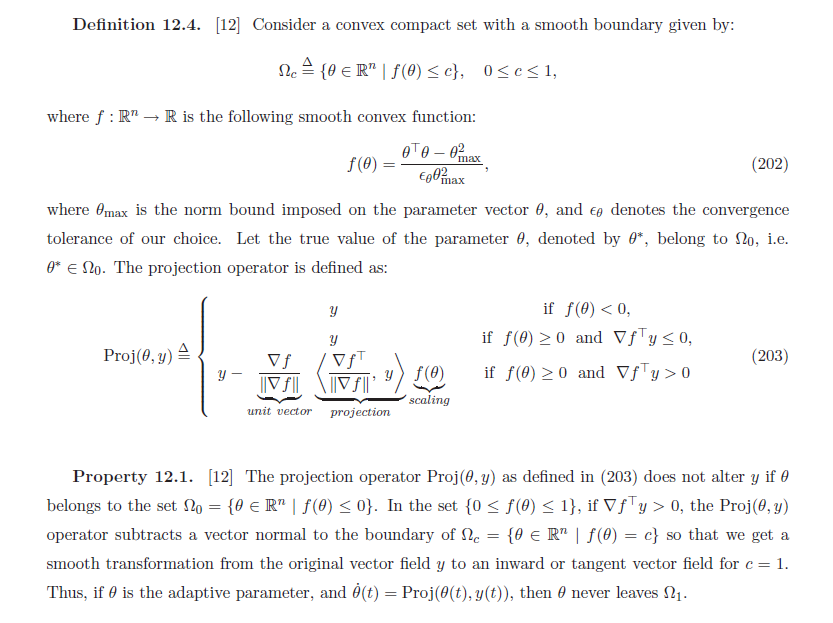

For the reduced 1st order system, we did not add a boundary layer, rather just a hard coded saturation value doing our work for the projection algorithm.

Our main objective is to keep the $\theta^{\star }$ within the convex set of $\theta$. Thus I have a limit of how much I can reduce the $\theta_{\max }$ as if my $\theta_{\max }$ is smaller than $\theta^{\star }$ then my star value is out of the convex set now !!

So if you see the code !! My projection algorithm is something like:

if $\theta_r <\left(\textrm{some}\;\textrm{threshold}\;\textrm{value}\;G\right)\;\;\textrm{and}\;\dot{\theta_r } <0\;\;\;\left(\textrm{That}\;\textrm{it}\;\textrm{is}\;\textrm{it}\;\textrm{is}\;\textrm{trying}\;\textrm{make}\;\theta_r \;\textrm{even}\;\textrm{more}-\textrm{ve}\right)\;$$\textrm{then}\;\textrm{make}\;\dot{\theta_r } \;=0$$\textrm{and}\;\textrm{replace}\;\textrm{time}\;\textrm{derivative}\;\textrm{of}\;\textrm{the}\;\textrm{Lyapunov}\;\textrm{function}\;\textrm{such}\;\textrm{that}\;\textrm{you}\;\textrm{add}\;\textrm{some}\;\textrm{positive}\;\textrm{terms}\;\textrm{to}\;\textrm{it}\;$

**Note**: Our threshold value G needs to be smaller than the theta_r star value because only then our adaptive theta_r value has a chance to learn and adapt !! BECAUSE NOTE: I know my theta_star value is positive and if I do not put a thershold then my adaptive theta value will be moving between positive and negative and whenever it enters a negative region, it is not really learning anything, so adding a threshold in positive region smaller than our positive theta star vlaue helps our adaptive value to remain in that positive region continuously and learn faster !!

Projection is important to have the right estimation of our Lyapunov function derviative as at each interval when the $\theta_r$ value reaches and passes saturation level, we have those extra negative saturation terms that we are missing in our estimate and eventually our Lyapunov functions do not match !! 

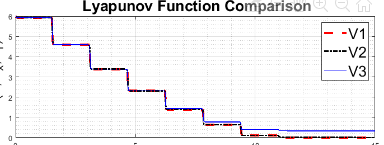

## **Full 2nd Order System:**

We are going to be working with a **Full state feedback system** here, with only $\omega$, as we are assuming that only $\omega$ is measureable. In order to use both $\omega$ and $\omega^˙$, we need to construct a **full output feedback system**.

$J\ldotp \frac{d}{\mathrm{d}t}\omega \;=-B\ldotp \omega \left(t\right)\;+K\ldotp i\left(t\right)$**                                     -   (1)**

$L\ldotp \frac{d}{\mathrm{d}t}i\;=-K\ldotp \omega \left(t\right)\;-R\ldotp i\left(t\right)+v\left(t\right)$**                            -   (2)**

**Differentiating the above equation (1):**

$J\cdot \omega^¨ =-B\ldotp \omega^˙ \;+K\ldotp \dot{i}$                                                **-  (3)**

Substitute value of $\dot{i}$ from Equation (2) to Equation (6)


$$\omega^¨ =-\frac{B}{J}\ldotp \omega^˙ \;+\frac{K}{J}\ldotp \left(-\frac{K}{L}\ldotp \omega -\frac{R}{L}\ldotp i+\frac{1}{L}\cdot v\right)$$



$$\Longrightarrow \omega^¨ =\left(-\frac{B}{J}\right)\ldotp \omega^˙ \;-\frac{K^2 }{\textrm{JL}}\cdot \omega -\frac{\textrm{KR}}{\textrm{JL}}\cdot i+\frac{K}{\textrm{JL}}v$$


Substitute value of i from Equation 1 to the above equation 


$$\Longrightarrow \omega^¨ =\left(-\frac{B}{J}\right)\ldotp \omega^˙ \;-\frac{K^2 }{\textrm{JL}}\cdot \omega -\frac{\textrm{KR}}{\textrm{JL}}\cdot \left(\frac{J\cdot \omega^˙ \;\;+\;B\cdot \omega }{K}\right)+\frac{K}{\textrm{JL}}v$$



$$\Longrightarrow \omega^¨ =\left(-\frac{B}{J}-\frac{R}{L}\right)\ldotp \omega^˙ \;-\left(\frac{K^2 }{\textrm{JL}}+\frac{\textrm{RB}}{\textrm{JL}}\right)\cdot \omega \;+\frac{K}{\textrm{JL}}v$$


Let $\alpha =\left(-\frac{B}{J}-\frac{R}{L}\right)$, $\beta =-\left(\frac{K^2 }{\textrm{JL}}+\frac{\textrm{RB}}{\textrm{JL}}\right)$, and $\delta =\frac{K}{\textrm{JL}}$

Let X = $\left\lbrack \begin{array}{c}
\omega \\
\omega^˙ 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
x_1 \\
x_2 
\end{array}\right\rbrack$, where $\dot{x_1 } =x_2 =\omega^˙$, and $\dot{x_2 } =\omega^¨ =\alpha \ldotp \omega^˙ \;\;+\beta \cdot \omega \;+\delta v$ 

Therefore, $\dot{X}$ = $\left\lbrack \begin{array}{c}
\dot{x_1 } \\
\dot{x_2 } 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
0 & 1\\
\beta  & \alpha 
\end{array}\right\rbrack \cdot \left\lbrack \begin{array}{c}
x_1 \\
x_2 
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
0\\
\delta 
\end{array}\right\rbrack \cdot v$

$\overset{\star }{A}$ = $\left\lbrack \begin{array}{cc}
0 & 1\\
\beta  & \alpha 
\end{array}\right\rbrack$, $\overset{\star }{B}$ = $\left\lbrack \begin{array}{c}
0\\
\delta 
\end{array}\right\rbrack$ , Let it be: 

$\overset{\star }{A}$ = $\left\lbrack \begin{array}{cc}
0 & 1\\
\overset{\star }{a_1 }  & \overset{\star }{a_2 } 
\end{array}\right\rbrack$, $\overset{\star }{B}$ = $\left\lbrack \begin{array}{c}
0\\
\overset{\star }{b} 
\end{array}\right\rbrack$, for easy variables to recognise

$\dot{X} \;=\overset{\star }{A} \cdot X+\overset{\star }{B} \cdot U$                                                                **- (4)**

 **Note**: $U=\left\lbrack \begin{array}{c}
0\\
u
\end{array}\right\rbrack$

## **Reference system:**

$X_r =\left\lbrack \begin{array}{c}
x_{\textrm{r1}} \\
x_{\textrm{r2}} 
\end{array}\right\rbrack$, such that:                                                             **- (5)**

$\dot{X_r } \;=A_r \ldotp X_r +B_r \ldotp r$ = $\left\lbrack \begin{array}{c}
\dot{x_{\textrm{r1}} } \\
\dot{x_{\textrm{r2}} } 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
0 & 1\\
a_{\textrm{r1}}  & a_{\textrm{r2}} 
\end{array}\right\rbrack \cdot \left\lbrack \begin{array}{c}
x_{\textrm{r1}} \\
x_{\textrm{r2}} 
\end{array}\right\rbrack \;\;+\left\lbrack \begin{array}{c}
0\\
b_r 
\end{array}\right\rbrack \cdot r=\;\left\lbrack \begin{array}{c}
x_{\textrm{r2}} \\
a_{\textrm{r1}} \cdot x_{\textrm{r1}} +a_{\textrm{r2}} \cdot x_{\textrm{r2}} +b_r \cdot r
\end{array}\right\rbrack$,     **- (6)**            $X_r \;\to X_d \;\left(\textrm{desired}\;\textrm{signal}\right)$             

$X_d \;=\left\lbrack \begin{array}{c}
x_d \\
\dot{x_d } 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
10*\sin \left(2\cdot t\right)\\
20*\cos \left(2\cdot t\right)
\end{array}\right\rbrack$**                                               - (7)**

## **Star Controller:**

**(Controller for MRC)**    $u=\;\left({\overset{\star }{{\;\theta }_x } }^T \cdot X+\overset{\star }{\theta_r } \cdot r\right)$       , T stands for Transpose            **- (8)**

where, $\overset{\star }{{\;\theta }_x } =\left\lbrack \begin{array}{c}
\overset{\star }{\theta_{\textrm{x1}} } \\
\overset{\star }{\theta_{\textrm{x2}} } 
\end{array}\right\rbrack$, and X = $\left\lbrack \begin{array}{c}
\omega \\
\omega^˙ 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
x_1 \\
x_2 
\end{array}\right\rbrack$

such that $u=\;\left(\overset{\star }{\theta_{\textrm{x1}} } \cdot x_1 \;+\overset{\star }{\theta_{\textrm{x2}} } \cdot x_2 \;+\overset{\star }{\theta_r } \cdot r\right)$                               - **(9)**

In MRAC since $\overset{\star }{\theta_x } \;$and $\overset{\star }{\theta_r } \;$ values are unknown to us, Therefore in that case we would define a controller with adaptive components

$\theta_x$ and $\theta_r$ such that $\theta_x$ and $\theta_r$ converge to $\overset{\star }{\theta_x } \;$and $\overset{\star }{\theta_r } \;$ values for the system to work as intended.

**(Controller for MRAC)**    $u=\left({\theta_x }^T \cdot X+\theta_r \cdot r\right)$                        **(10)**

Similar to above**: **$u=\;\left(\theta_{\textrm{x1}} \cdot x_1 \;+\theta_{\textrm{x2}} \cdot x_2 \;+\theta_r \cdot r\right)$                   **- (11)**

**Note**: For our controller function if we just have $\overset{\star }{\theta_x } \;$and $\overset{\star }{\theta_r } \;$(Constants)

instead of adaptive $\theta_x$ and $\theta_r$, then it is known as the **Model Reference Control approach using the Star Controller**

 vol = controller(r,om,txstar, trstar)

## **Using Star Controller to close the loop:**

$\dot{X} \;=\overset{\star }{A} \cdot X+\overset{\star }{B} \cdot U=\left\lbrack \begin{array}{c}
\dot{x_1 } \\
\dot{x_2 } 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
x_2 \\
\overset{\star }{a_1 } \cdot x_1 +\overset{\star }{a_2 } \cdot x_2 +\overset{\star }{b} \cdot u
\end{array}\right\rbrack$                Revisiting **Equation 4**

$\dot{X_r } \;=A_r \ldotp X_r +B_r \ldotp r$ = $\left\lbrack \begin{array}{c}
\dot{x_{\textrm{r1}} } \\
\dot{x_{\textrm{r2}} } 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
x_{\textrm{r2}} \\
a_{\textrm{r1}} \cdot x_{\textrm{r1}} +a_{\textrm{r2}} \cdot x_{\textrm{r2}} +b_r \cdot r
\end{array}\right\rbrack$            Revisiting **Equation 6**

To close the loop, we use the $\dot{x_2 }$ from **Equation 4** since it has the controller element and input the star controller u from **Equation 9**


$$\dot{x_2 } \;=\overset{\star }{a_1 } \cdot x_1 +\;\overset{\star }{a_2 } \cdot x_2 +\overset{\star }{b} \cdot \left(\overset{\star }{\theta_{\textrm{x1}} } \cdot x_1 \;+\overset{\star }{\theta_{\textrm{x2}} } \cdot x_2 +\overset{\star }{\theta_r } \cdot r\right)$$



$$\dot{x_2 } \;=\left(\overset{\star }{a_1 } +\overset{\star }{b} \cdot \overset{\star }{\theta_{\textrm{x1}} } \right)\cdot x_1 +\;\left(\overset{\star }{a_2 } +\overset{\star }{b} \cdot \overset{\star }{\theta_{\textrm{x2}} } \right)\cdot x_2 +\overset{\star }{b} \cdot \overset{\star }{\theta_r } \cdot r$$
        

**Note**: Here we would have to assume for our** Compatibility equation** $a_{\textrm{r1}} =\left(\overset{\star }{a_1 } +\overset{\star }{b} \cdot \overset{\star }{\theta_{\textrm{x1}} } \right)$, $a_{\textrm{r2}} =\left(\overset{\star }{a_2 } +\overset{\star }{b} \cdot \overset{\star }{\theta_{\textrm{x2}} } \right)$ and $b_r =\left(\overset{\star }{b} \cdot \overset{\star }{\theta_r } \right)$,    

**Therefore:**

$\overset{\star }{\theta_{\textrm{x1}} } \;=\;\frac{a_{\textrm{r1}} -\overset{\star }{a_1 } }{\overset{\star }{b} }$  ,  $\overset{\star }{\theta_{\textrm{x2}} } \;=\;\frac{a_{\textrm{r2}} -\overset{\star }{a_2 } }{\overset{\star }{b} }$           and           $\overset{\star }{\theta_r } \;=\;\frac{b_r }{\overset{\star }{b} }$

## **Error Dynamics assumption:**

$e_r =X_r -X_d =\left\lbrack \begin{array}{c}
x_{\textrm{r1}} \\
x_{\textrm{r2}} 
\end{array}\right\rbrack -\left\lbrack \begin{array}{c}
x_d \\
\dot{x_d } 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
x_{\textrm{r1}} -x_d \\
x_{\textrm{r2}} -\dot{x_d } 
\end{array}\right\rbrack$                                                                               **(12)**

$\dot{e_r } =\dot{X_r } -\dot{X_d } \;=\left\lbrack \begin{array}{c}
x_{\textrm{r2}} \\
a_{\textrm{r1}} \cdot x_{\textrm{r1}} +a_{\textrm{r2}} \cdot x_{\textrm{r2}} +b_r \cdot r
\end{array}\right\rbrack -\left\lbrack \begin{array}{c}
\dot{x_d } \\
\ddot{x_d } 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
x_{\textrm{r2}} -\dot{x_d } \\
a_{\textrm{r1}} \cdot x_{\textrm{r1}} +a_{\textrm{r2}} \cdot x_{\textrm{r2}} +b_r \cdot r-\ddot{x_d } 
\end{array}\right\rbrack$           **(13)**

$\dot{e_r } =A_r \cdot e_r$             Expectation $e_r \;\to 0$  as $X_r \;\to X_d$

                    
$$\Longrightarrow$$
 
$$\dot{X_r } -\dot{X_d } \;=A_r \cdot e_r$$


                    
$$\Longrightarrow$$
 
$$\dot{X_r } -\dot{X_d } \;=A_r \cdot \left(X_r -X_d \right)$$


                    $\Longrightarrow$ $\dot{X_r } \;=A_r \cdot \left(X_r -X_d \right)+\dot{X_d }$         **(14)**

Comparing Equation** (6) **and Equation **(14)**

$A_r \ldotp X_r +B_r \ldotp r$ = $A_r \cdot \left(X_r -X_d \right)+\dot{X_d }$

$B_r \ldotp r$ = $-A_r \cdot X_d \;+\dot{\;X_d }$    


$$\Longrightarrow \left\lbrack \begin{array}{c}
0\\
b_r 
\end{array}\right\rbrack \cdot r=-\left\lbrack \begin{array}{cc}
0 & 1\\
a_{\textrm{r1}}  & a_{\textrm{r2}} 
\end{array}\right\rbrack \cdot \left\lbrack \begin{array}{c}
x_d \\
\dot{x_d } 
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
\dot{x_d } \\
\ddot{x_d } 
\end{array}\right\rbrack$$


Focusing on equation in the 2nd row


$$\Longrightarrow b_r \cdot r=\ddot{x_d } -a_{\textrm{r1}} \cdot x_d -a_{\textrm{r2}} \cdot \dot{x_d }$$


$\Longrightarrow$ $r$ = $\frac{\left(\ddot{x_d } -a_{\textrm{r1}} \cdot x_d -a_{\textrm{r2}} \cdot \dot{x_d } \right)}{b_r }$       **(12)**          **(Reference controller element)**

**Further For MRAC (Adding Adaptive component)**

$e=X-X_r$            **(13)**


$$e=\left\lbrack \begin{array}{c}
e_1 \\
e_2 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
x_1 -x_{\textrm{r1}} \\
x_2 -x_{\textrm{r2}} 
\end{array}\right\rbrack$$


Note: $e_2 =\dot{e_1 }$

$\dot{e} =\dot{X} -\dot{X_r } \;$           **(14)**

Adding and subtracting  $\left(A_r \cdot X\right)$ to the above equation

$\Longrightarrow$$\dot{e} =\dot{X} -\dot{X_r } \;$ + $\left(A_r \cdot X\right)$ - $\left(A_r \cdot X\right)$

Input value of $\dot{X} \;\;\;\textrm{and}\;\;\dot{X_r }$   from Equation **(3)** and **(4)**

$\Longrightarrow$$\dot{e} =\left(\overset{\star }{A} \cdot X+\overset{\star }{B} \cdot U\right)-\left(A_r \ldotp X_r +B_r \ldotp r\right)\;$ + $\left(A_r \cdot X\right)$ - $\left(A_r \cdot X\right)$

Input value of the **adaptive controller** u from Equation **(8),**

$\Longrightarrow$$\dot{e} =\left(\overset{\star }{A} \cdot X\;+\overset{\star }{B} \ldotp \left({\overset{\star }{{\;\theta }_x } }^T \cdot X+\overset{\star }{\theta_r } \cdot r\right)\right)-\left(A_r \ldotp X_r +B_r \ldotp r\right)\;$ + $\left(A_r \cdot X\right)$ - $\left(A_r \cdot X\right)$

In a closed loop we know,  $A_r =\left(\overset{\star }{A} +\overset{\star }{\;B} \cdot \overset{\star }{\theta_x } \right)$ and $B_r =\overset{\star }{B} \cdot \overset{\star }{\theta_r }$,   


$$\Longrightarrow$$

$$\dot{e} =\left(\overset{\star }{A} \right)\cdot X\;+\;\;\;\overset{\star }{B} \cdot \theta_x \cdot X\;\;\;+\;\overset{\star }{\;B} \cdot \theta_r \cdot r\;\;\;\;+\;\left(X-X_r \right)\cdot A_r \;-\left(B_r \right)\cdot r\;-\left(\overset{\star }{A} +\overset{\star }{\;B} \cdot \overset{\star }{\theta_x } \right)\ldotp X$$
 

$\Longrightarrow$$\dot{e} =\;\;\left(X-X_r \right)\cdot A_r$  + $\overset{\star }{\;B} \cdot \theta_r \cdot r$ - $\overset{\star }{B} \cdot \overset{\star }{\theta_r }$$\cdot r\;+\;\;\overset{\star }{\;B} \cdot \theta_x \cdot X\;\;-\;\;\;\overset{\star }{B} \cdot \overset{\star }{\theta_x } \cdot X$

We know $e=X-X_r$ from Equation **(12) **also $\tilde{\theta_x } =\theta_X -\overset{\star }{\theta_X }$    and $\tilde{\theta_r } =\theta_r -\overset{\star }{\theta_r }$


$$\Longrightarrow$$

$$\dot{e} =A_r \cdot e+\overset{\star }{\;B} \cdot \tilde{\theta_x } \cdot X\;\;+\overset{\star }{\;B} \cdot \tilde{\theta_r } \cdot r$$
      


$$\Longrightarrow$$
 
$$\dot{e} =A_r \cdot e\;+\left\lbrack \begin{array}{c}
0\\
\overset{\star }{b} 
\end{array}\right\rbrack \cdot \tilde{\theta_x } X\;\;+\left\lbrack \begin{array}{c}
0\\
\overset{\star }{b} 
\end{array}\right\rbrack \cdot \tilde{\theta_r } \cdot r$$
         

## **For our Adaptive controller we also need to prove stability of the chosen Lyapunov Function**

Now if we close the controller loop with adaptive $\theta_x$ and $\theta_r$ this becomes MRAC;  vol = controller(r,om,tx, tr)

**Lyapunov Function  **$V\left(\tilde{\theta_x } \;,\tilde{\theta_r } \;\;,e,P_2 \right)$**:**

$V=e^T \cdot P\cdot e\;+\;\frac{\left|b\right|}{\gamma_x }\cdot {\tilde{\theta_x } }^2 \;+\;\frac{\left|b\right|}{\gamma_r }\cdot {\tilde{\theta_r } }^2$   ,   $\gamma_x \;\;\textrm{and}\;\gamma_r \;\;\textrm{are}\;\textrm{constant}\;\textrm{tuning}\;\textrm{gains}$

**Note:** $A^T \cdot P\;+P\cdot A+Q=0$,  Q is Positive definite

$\dot{V} =e\cdot \dot{e} +\;\frac{\left|\overset{\star }{b} \right|\cdot \tilde{\theta_x } \cdot \dot{\theta_x } }{\gamma_x }\;\;\;+\frac{\left|\overset{\star }{b} \right|\cdot \tilde{\theta_r } \cdot \dot{\theta_x } }{\gamma_r }$,      **(15)**          **Note:** $\tilde{\theta_x } =\theta_X -\overset{\star }{\theta_X } \;;\textrm{Therefore}\;$$\dot{\tilde{\theta_x } }$ = $\dot{\theta_x }$

Input value of $\dot{e}$ from **(13)**


$$\Longrightarrow$$

$$\dot{V} =e\cdot \left(A_r \cdot e\;+\left\lbrack \begin{array}{c}
0\\
\overset{\star }{b} 
\end{array}\right\rbrack \cdot {\tilde{\theta_x } }^T \cdot X\;\;+\left\lbrack \begin{array}{c}
0\\
\overset{\star }{b} 
\end{array}\right\rbrack \cdot \tilde{\theta_r } \cdot r\right)+\;\frac{\left|\overset{\star }{b} \right|\cdot \tilde{\theta_x } \cdot \dot{\theta_x } }{\gamma_x }\;\;\;+\frac{\left|\overset{\star }{b} \right|\cdot \tilde{\theta_r } \cdot \dot{\theta_x } }{\gamma_r }$$



$$\Longrightarrow$$

$$\dot{V} =a_r \cdot e^2 \;\;+\tilde{{\;\theta }_x } \cdot \left(\overset{\star }{\;b} \cdot x\cdot e\;+\;\frac{\left|\overset{\star }{b} \right|\cdot \dot{\theta_x } }{\gamma_x }\right)\;+\tilde{{\;\theta }_r } \cdot \left(\overset{\star }{\;b} \cdot r\cdot e\;+\;\frac{\left|\overset{\star }{b} \right|\cdot \dot{\theta_r } }{\gamma_r }\right)\;$$


We know: $\overset{\star }{b}$ = $\left|\overset{\star }{b} \right|\cdot \textrm{sign}\left(\overset{\star }{b} \right)$


$$\Longrightarrow$$

$$\dot{V} =-e^T \cdot Q\cdot e\;+\;\left|\overset{\star }{b} \right|\cdot {\tilde{{\;\theta }_x } }^T \cdot \left(e^T \cdot P_2 \cdot x\cdot \mathrm{sign}\left(\overset{\star }{b} \right)+\;\frac{\dot{\theta_r } }{\gamma_x }\right)\;+\left|\overset{\star }{b} \right|\cdot {\tilde{{\;\theta }_r } }^T \cdot \left(e^T \cdot P_2 \cdot r\cdot \mathrm{sign}\left(\overset{\star }{b} \right)+\;\frac{\dot{\theta_r } }{\gamma_r }\right)\;$$


**Note:** $P\cdot \left\lbrack \begin{array}{c}
0\\
b
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
P_1  & P_2 
\end{array}\right\rbrack \cdot \left\lbrack \begin{array}{c}
0\\
b
\end{array}\right\rbrack =\;P_2 \cdot b$


$$\Longrightarrow$$

$$\dot{V} =-e^T \cdot Q\cdot e\;+\;\left|\overset{\star }{b} \right|\cdot {\tilde{{\;\theta }_x } }^T \cdot \left(e^T \cdot P_2 \cdot x\cdot \textrm{sign}\left(\overset{\star }{b} \right)+\;\frac{\dot{\theta_r } }{\gamma_x }\right)\;+\left|\overset{\star }{b} \right|\cdot {\tilde{{\;\theta }_r } }^T \cdot \left(e^T \cdot P_2 \cdot r\cdot \textrm{sign}\left(\overset{\star }{b} \right)+\;\frac{\dot{\theta_r } }{\gamma_r }\right)\;$$


In order to keep $\dot{V} \left(t\right)$**strictly negative definite** we need coefficients of $\left|\overset{\star }{b} \right|\cdot {\tilde{{\;\theta }_x } }^T$  and $\left|\overset{\star }{b} \right|\cdot {\tilde{{\;\theta }_r } }^T$  to be 0

Which makes, value of $\dot{\theta_x }$ and $\dot{\theta_r }$ is:

$\dot{\theta_x } =-\gamma_x \cdot e^T \cdot P_2 \cdot x\cdot \textrm{sign}\left(\overset{\star }{b} \right)$                **(16)**

$\dot{\theta_r } =-\gamma_r \cdot e^T \cdot P_2 \cdot r\cdot \textrm{sign}\left(\overset{\star }{b} \right)$                 **(17)**

**Note: **Theta x1 and theta_x2 and theta_r are not supposed to converge because this is a second order system with a sinusoidal input which is not a persistent excitation (matrix should be positive definite all the time)

## Projection Algorithm 

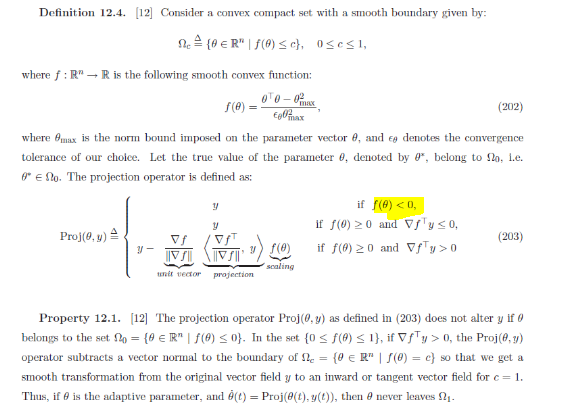

**What do we want ?**

We want to be 0 (zero) level set that is our $f\left(\theta \right)<0$ all the time !! If $f\left(\theta \right)\ge 0\;\left(\mathrm{Outside}\;\mathrm{the}\;\mathrm{region}\right)\;\mathrm{and}\;\nabla f^T y\le 0\;\left(\mathrm{That}\;\mathrm{is}\;\mathrm{we}\;\mathrm{are}\;\mathrm{pointing}\;\mathrm{inwards}\right)$, pointing towards the region (normal velocity vector inwards) then we are still good and can keep using what we have for projection !! But in case $f\left(\theta \right)\ge 0\;\left(\mathrm{Outside}\;\mathrm{the}\;\mathrm{region}\right)$ and $\nabla f^T y\;\;>0\;\left(\mathrm{normal}\;\mathrm{velocity}\;\mathrm{vector}\;\mathrm{pointing}\;\mathrm{outwards}\right)$

**Note:** The direction of our normal velcoity vector $\nabla f^T y$, Outwards for > 0 and Inwards for < 0, determines which direction we are trying to head to 

We first define our **convex f function (scaling)** is : $f\left(\theta \right)=\frac{\theta^T \theta -{\theta_{\mathrm{max}} }^2 }{\varepsilon_0 \cdot {\theta_{\mathrm{max}} }^2 }$, where $\theta_{\mathrm{max}} \;\mathrm{and}\;\varepsilon_0 \;\mathrm{are}\;\mathrm{our}\;\mathrm{tuning}\;\mathrm{parameters}$

The we define our **gradient of f**: $\nabla f=\frac{\partial }{\partial \theta }f\left(\theta \right)=\frac{2\cdot \theta }{\varepsilon_0 \cdot {\theta_{\mathrm{max}} }^2 }$, **note:** $\theta_{\mathrm{max}}$ is a constant so in the numerator with derivative w.r.t $\theta$ it becomes 0

**Norm of gradient of f**: $\left\|\nabla f\right\|$, can simply use **norm()** function in Matlab

**Normalized gradient of f (Our unit vector)**: $\frac{\nabla f}{\left\|\nabla f\right\|}$

**Normal velocity vector** (Our normal vector to the level set):  $\nabla f^T y$, In our case y is $\theta^˙$

For our** Projection part of the (203) equation** above: $\left\langle {\frac{\nabla f}{\left\|\nabla f\right\|}}^T ,y\right\rangle ={\frac{\nabla f}{\left\|\nabla f\right\|}}^T \cdot \mathrm{adjoint}\;\left(y\right)$ , Usually also referred to as the expectation value

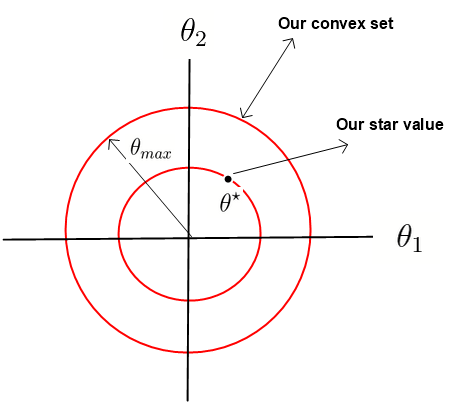

**WHAT WE LEARNED FOR APPLICATION IN REALITY:**

**NOTE:**  In reality we will never have the star values, star values are usually used to compute and plot the lyapunov function and thus eventhough we would be able to implement Adaptive controller, we would not be able to plot the lyapunov function for it.

## **Reduced First Order System**

## **System Parameters**

% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% %------ True value of Motor and Load parameters -----%
% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% J = 0.0026;
% B = 0.00057;
% R = 0.5;
% K = 0.56;
% 
% % If we want to reduce the system to a 1st order system
% % We can assume L very small, and thus approximately 0 
% % L = 0.0045;  
% 
% % To simulate Second Order system we would uncomment the above
% % and not assume L to be 0
% % Also uncomment the Full Second Order Subsystem in the Simulink Model !!
% 
% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% %------ True value of Unknown Deadzone parameters -----%
% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% m = 2;
% b_r = 0.8;
% b_l = -1.2;
% 
% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% %------ Definition of Astar and Bstar Reduced 1st Order -----%
% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% % by modified Eq. 2 (L negligible) 
% astar = -(B*R+K^2)/(R*J);
% bstar = K/(R*J);
% 
% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% %------ Constant Reference Inputs, Reduced 1st Order -----%
% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% % Can change these gain values based on our response
% % Smaller ar -> smaller vdot
% ar = -15;   
% br = 15;
% % at ar = -1 and br = 1, we see tr_star = 0.0023, but we have put a
% % saturation at 0.01 as the bound is above the theta_star, therefore it
% % never is able to converge and always bounces back from 0.01
% 
% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% %------ Adaptive Parameters (gamma_x and gamma_r), Reduced 1st Order -----%
% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% % MRC, using star Controller (Without  making the system adaptive)
% % Theta_x_star, Theta_r_star are Constants
% 
% tx_star = (ar - astar)/bstar; 
% tr_star = br/bstar; 
% 
% % For MRAC, tuning parameters
% % higher values of gam_x and gam_r Cause of oscillations for gains (theta_x, and theta_R)
% % Our qualitative goal is to minimize those oscillations
% gam_x = 10;
% gam_r = 10;
% 
% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% %------ Initial Conditions, Reduced 1st Order -----%
% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% x0=0; xr0=0;
% e0 = x0 - xr0;
% thx0 = 0;
% thr0 = 0;
% cur0 = 0;
% 
% V0 = .5*e0^2 + .5*abs(bstar)/gam_x*(thx0 - tx_star)^2 + .5*abs(bstar)/gam_r*(thr0 - tr_star)^2; % Lyapunov Function
% 
% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% %------ Extracting Data from Simulink to Workspace -----%
% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% out = sim('Linear_scalar_Part1');                 % Reduced 1st order system and 2nd order
% % out = sim('AdaptiveControlsProjectPart1_Sethi'); 
% % Just change the simulink blocks used for each system
% 
% 
% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% %------ Variable Assignment, Reduced 1st Order -----%
% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% 
% tout = out.tout;
% x = out.x;
% xr = out.xr;
% xd = out.xd;
% 
% u = out.u; % Controller
% 
% Error_ref = out.xr - out.xd;
% Error = x - xr;
% 
% thx = out.thx;
% thr = out.thr;
% dthx = out.dthx;
% dthr = out.dthr;
% 
% V1 = out.V1;
% V2 = out.V2;
% V3 = out.V3;
% 
% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% %------ Lyapunov Function Stability check -----%
% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% % To Check if the Lyapunov function is strictly devreasing over time and thus the derivative is negative definite
% V1fail = 0;
% V2fail = 0;
% V3fail = 0;
% for i = 1:(length(V1)-1)
%     if (V1(i+1) - V1(i))>1e-8
%         V1fail = V1fail + 1;
%     end
%     if (V2(i+1) - V2(i))>1e-8
%         V2fail = V2fail + 1;
%     end
%     if (V3(i+1) - V3(i))>1e-8
%         V3fail = V3fail + 1;
%     end
% end
% 
% V1fail
% V2fail
% V3fail
% 
% 
% if V1fail == 0
%     disp('V1 Passed')
% else
%     disp('V1 failed')
% end
% 
% if V2fail == 0
%     disp('V2 Passed')
% else
%     disp('V2 failed')
% end
% 
% if V3fail == 0
%     disp('V3 Passed')
% else
%     disp('V3 failed')
% end
% 
% eV = abs(V1 - V2);
% eVavg = mean(eV)
% 
% % %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% % %------ Desired, Reference and Actual Trajectory(Omega) -----%
% % %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% 
% figure()
% subplot(3, 2, 1)
% plot(tout, x, 'LineWidth', 3, 'LineStyle', '--', 'Color', 'r'); 
% hold on
% grid on
% grid minor
% axis tight
% plot(tout, xr, 'LineWidth', 2, 'LineStyle', '-.', 'Color', 'k'); 
% plot(tout, xd, 'LineWidth', 1, 'Color', 'b');  
% yline(10,'--','Max limit for u','LineWidth',2);
% yline(-10,'--','Min limit for u','LineWidth',2);
% ylim([-12 12]);
% lgd = legend('Actual (x = \omega)', 'Reference (x_r = \omega_r)', 'Desired (x_d = \omega_d)', 'interpreter', 'tex');
% lgd.FontSize = 15;
% xlabel('\fontsize{20} Time (seconds)', 'interpreter', 'tex'); 
% ylabel('\fontsize{20} Angular Velocity deg/s', 'interpreter', 'tex'); 
% title('\fontsize{20} Desired, Actual and Reference Trajectory Comparison', 'interpreter', 'tex');
% hold off
% 
% % In order to maximize the figure window in Windows
% set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, 1, 0.96]);
% %%%%%%%%%%%%%%%%%%%%
% %------ Error -----%
% %%%%%%%%%%%%%%%%%%%%
% 
% subplot(3, 2, 2)
% plot(tout, Error, 'LineWidth', 2, 'LineStyle', '--', 'Color', 'r'); 
% hold on
% grid on
% grid minor
% axis tight
% plot(tout, Error_ref, 'LineWidth', 1, 'LineStyle', '-.', 'Color', 'k');
% yline(10,'--','Max limit for u','LineWidth',2);
% yline(-10,'--','Min limit for u','LineWidth',2);
% ylim([-12 12]);
% lgd = legend('Error (e = x - x_r)', 'Error reference (e_r = x_r - x_d)', 'interpreter', 'tex');
% lgd.FontSize = 15;
% xlabel('\fontsize{20} Time (seconds)', 'interpreter', 'tex'); 
% ylabel('\fontsize{20} Error', 'interpreter', 'tex'); 
% title('\fontsize{20} Actual and Reference Error Comparison', 'interpreter', 'tex');
% hold off
% % In order to maximize the figure window in Windows
% set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, 1, 0.96]);
% 
% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% %------ Reference and Actual Adaptive Parameters -----%
% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% % Take care of the oscillation 
% subplot(3,2, 3)
% plot(tout, thx, 'LineWidth', 2, 'LineStyle', '--', 'Color', 'r'); 
% hold on
% grid on
% grid minor
% axis tight
% plot(tout,thr, 'LineWidth', 2, 'LineStyle', '-.', 'Color', 'b');
% yline(tx_star,'--', 'tx_star','LineWidth',1);
% yline(tr_star,'--', 'tr_star','LineWidth',1);
% % xlim([0, max(t)]); 
% % ylim([-12 12]);
% lgd = legend('$\theta_x$', '$\theta_r$','${\theta_x}^{\star}$', '${\theta_r}^{\star}$', 'interpreter', 'latex');
% lgd.FontSize = 20; lgd.Location = 'southwest';
% xlabel('\fontsize{20} Time (seconds)', 'interpreter', 'tex'); 
% ylabel('\fontsize{20} Adaptive Parameters', 'interpreter', 'tex'); 
% title('\fontsize{20} Actual & Reference Adaptive Parameters Comparison', 'interpreter', 'tex');
% hold off
% 
% 
% subplot(3,2, 4)
% plot(tout,dthx, 'LineWidth', 1, 'LineStyle', '-.', 'Color', 'k'); 
% hold on
% grid on
% grid minor
% axis tight
% plot(tout,dthr, 'LineWidth', 1, 'LineStyle', '-.', 'Color', 'c');
% % yline(10,'--','Max limit for u','LineWidth',2);
% % yline(-10,'--','Min limit for u','LineWidth',2);
% % xlim([0, max(t)]); 
% % ylim([-12 12]);
% lgd = legend('$\dot{\theta_x}$', '$\dot{\theta_r}$', 'interpreter', 'latex');
% lgd.FontSize = 20; lgd.Location = 'southwest';
% xlabel('\fontsize{20} Time (seconds)', 'interpreter', 'tex'); 
% ylabel('\fontsize{20} Adaptive Parameters', 'interpreter', 'tex'); 
% title('\fontsize{20} Actual & Reference Adaptive Parameters Comparison', 'interpreter', 'tex');
% hold off
% 
% % %%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% % %------ Controller (u) -----%
% % %%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% 
% subplot(3, 2, 5)
% plot(tout, u, 'LineWidth', 1, 'LineStyle', '--', 'Color', 'r');      
% hold on
% grid on
% grid minor
% axis tight    
% % yline(10,'--','Max limit for u','LineWidth',2);
% % yline(-10,'--','Min limit for u','LineWidth',2);
% % xlim([0, max(tout)]); 
% % ylim([-12 12]);
% xlabel('\fontsize{20} Time (seconds)', 'interpreter', 'tex'); 
% ylabel('\fontsize{20} Controller (u)', 'interpreter', 'tex'); 
% title('\fontsize{20} Control Effort (u)', 'interpreter', 'tex');
% hold off
% 
% % %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% % %------ Lyapunov Function Comparison -----%
% % %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% % Lyapunov functions should be monotonically decreasing
% 
% subplot(3,2, 6)
% plot(tout, V1, 'LineWidth', 3, 'LineStyle', '--', 'Color', 'r'); 
% hold on
% grid on
% grid minor
% plot(tout, V2, 'LineWidth', 2, 'LineStyle', '-.', 'Color', 'k'); 
% plot(tout, V3, 'LineWidth', 1, 'Color', 'b'); 
% % yline(10,'--','Max limit for u','LineWidth',2);
% % yline(-10,'--','Min limit for u','LineWidth',2);
% % xlim([0, max(tout)]); 
% % ylim([-12 12]);
% lgd = legend('V1', 'V2', 'V3', 'interpreter', 'tex');
% lgd.FontSize = 20;
% xlabel('\fontsize{20} Time (seconds)', 'interpreter', 'tex'); 
% ylabel('\fontsize{20} V(e, \theta_x, \theta_r)', 'interpreter', 'tex'); 
% title('\fontsize{20} Lyapunov Function Comparison', 'interpreter', 'tex');
% hold off
% 
% % In order to maximize the figure window in Windows
% set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, 1, 0.96]);

## **Full Second Order System**

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%------ True value of Motor and Load parameters -----%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
J = 0.0026;
B = 0.00057;
R = 0.5;
K = 0.56;

% If we want to reduce the system to a 1st order system
% We can assume L very small, and thus approximately 0 
L = 0.0045;  

% To simulate Second Order system we would uncomment the above
% and not assume L to be 0
% Also uncomment the Full Second Order Subsystem in the Simulink Model !!

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%------ True value of Unknown Deadzone parameters -----%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
m = 2;
b_r = 0.8;
b_l = -1.2;

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% ------ Definition of Astar and Bstar, 2nd Order System -----%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
astar1 = -((K^2 + R*B)/J*L);  
astar2 = -((B/J) + (R/L));   
bstar = K/(J*L);             

Astar = [0, 1; astar1, astar2];
Bstar = [0; bstar]; 
% In reality Bstar = [0; bstar]; is a vector but we define it as a scalar
% for ease !!

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% ------ Constant Reference Inputs, 2nd Order System -----%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
ar1 = -100; % Just tune these values
ar2 = -80; % Just tune these values
br = 70;
Ar = [0, 1; ar1, ar2];   
Br = [0; br];
% In reality Br = [0; some gain value of your choice]; 

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% ------ Adaptive Parameters (gamma_x and gamma_r), 2nd Order System -----%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
Tx_star1 = (ar1 - astar1)/Bstar(2,1);     % Tx_star1 = (ar1 - astar1)/bstar; 
Tx_star2 = (ar2 - astar2)/Bstar(2,1);    % Tx_star2 = (ar2 - astar2)/bstar;
Tx_star = [Tx_star1; Tx_star2];
Tr_star = Br(2,1)/Bstar(2,1);           % tr_star = br/bstar; 

Gam_x = [.1 0; 0, .1];
Gam_r = .1;

Q = [1, 0; 0, 1];
P = lyap(Ar', Q);
% Splitting P into two halves P = [P1, P2]
P1 = P(:, 1);
P2 = P(:, 2);
% Note: lyap(A, Q) solves the Lyapunov matrix Equation: A*X + X*A' + Q = 0;
% But our Lyapunove equation is A'P + PA + Q = 0, So we will use lyap(A', Q)


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% ------ Projection Algorithm Stuff  -----%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% So when the vel_norm > th_max value, the saturation would kick and give
% us the saturated vel_norm2 [Those 2 in the adaptive subsystem]
th_max = 0.1 % Smaller value of th_max is moving my convF closer to > 0

th_max = 0.1000

eps_th = .1;
% Note: If we increase epsilon (eps_theta)

% So my th_max needs to be greater than norm(theta)-:{distance of theta star from
% origin}, so that the theta star is always withing the convex set (which is basically a circle with the_max as it's radius)
theta = [Tx_star; Tr_star];
fprintf('Norm of Theta is: %f', norm(theta));

Norm of Theta is: 0.002624

if norm(theta)< th_max
    disp('Theta star is within the convex state')
end

Theta star is within the convex state


% Note: We are looking at the convex F for Theta = theta_star
% I want convex F to be < 0, because if convex F > 0 then it means that the
% theta_star is outside of the set and that means our PROJECTION algo is
% not going to work
convF = (theta'*theta - th_max^2)/(eps_th*th_max^2)

convF = -9.9931


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% ------ Initial Conditions, Full 2nd Order -----%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
X0 = [0; 0]; Xr0 = [0; 0];
e0 = X0 - Xr0;
thx0 = [0; 0];
thr0 = 0;
cur0 = 0;
om0 = 0;

V0 = e0'*P*e0 + abs(Bstar(2,1))*(thx0 - Tx_star)'*inv(Gam_x)*(thx0 - Tx_star) + ...
              abs(Bstar(2,1))/Gam_r*(thr0 - Tr_star)^2;
          
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%------ Extracting Data from Simulink to Workspace -----%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%         
out = sim('AdaptiveControlsProjectPart1_Sethi');   % Reduced 1st order system and 2nd order
% Just change the simulink blocks used for each system

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% ------ Full, 2nd Order System -----%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
tout = out.tout;
x = out.x;
x1 = x(:, 1);
x2 = x(:, 2);

xr = out.xr;
xr1 = xr(:, 1);
xr2 = xr(:, 2);

xd = out.xd;
dxd = out.dxd;

u = out.u; % Controller

Error_ref1 = xr1 - xd; 
Error_ref2 = xr2 - dxd; 
Error_ref = [Error_ref1, Error_ref2];

thx = out.thx;
thx1 = thx(:,1);
thx2 = thx(:,2);
thr = out.thr;
dthx = out.dthx;
dthx1 = dthx(:,1);
dthx2 = dthx(:,2);
dthr = out.dthr;

% For 2nd Order System:
Error1 = x1 - xr1;
Error2 = x2 - xr2;
Error = [Error1, Error2];

V1 = out.V1;
V2 = out.V2;
V3 = out.V3;

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% ------ Projection Algorithm Stuff  -----%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Note: You have a time series data here so-
convexF = out.convexF;
time_projection = convexF.time;
convexF = convexF.Data(:,1);
velnormal = out.velnormal;
velnormal = velnormal.Data(:,1);
velnormal2 = out.velnormal2;
velnormal2 = velnormal2.Data(:,1);

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%------ Lyapunov Function Stability check -----%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% To Check if the Lyapunov function is strictly devreasing over time and thus the derivative is negative definite
V1fail = 0;
V2fail = 0;
V3fail = 0;
for i = 1:(length(V1)-1)
    if (V1(i+1) - V1(i))>1e-8
        V1fail = V1fail + 1;
    end
    if (V2(i+1) - V2(i))>1e-8
        V2fail = V2fail + 1;
    end
    if (V3(i+1) - V3(i))>1e-8
        V3fail = V3fail + 1;
    end
end

V1fail

V1fail = 0

V2fail

V2fail = 0

V3fail

V3fail = 0



if V1fail == 0
    disp('V1 Passed')
else
    disp('V1 failed')
end

V1 Passed



if V2fail == 0
    disp('V2 Passed')
else
    disp('V2 failed')
end

V2 Passed



if V3fail == 0
    disp('V3 Passed')
else
    disp('V3 failed')
end

V3 Passed



eV = abs(V1 - V2);
eVavg = mean(eV)

eVavg = 1.1572e-05

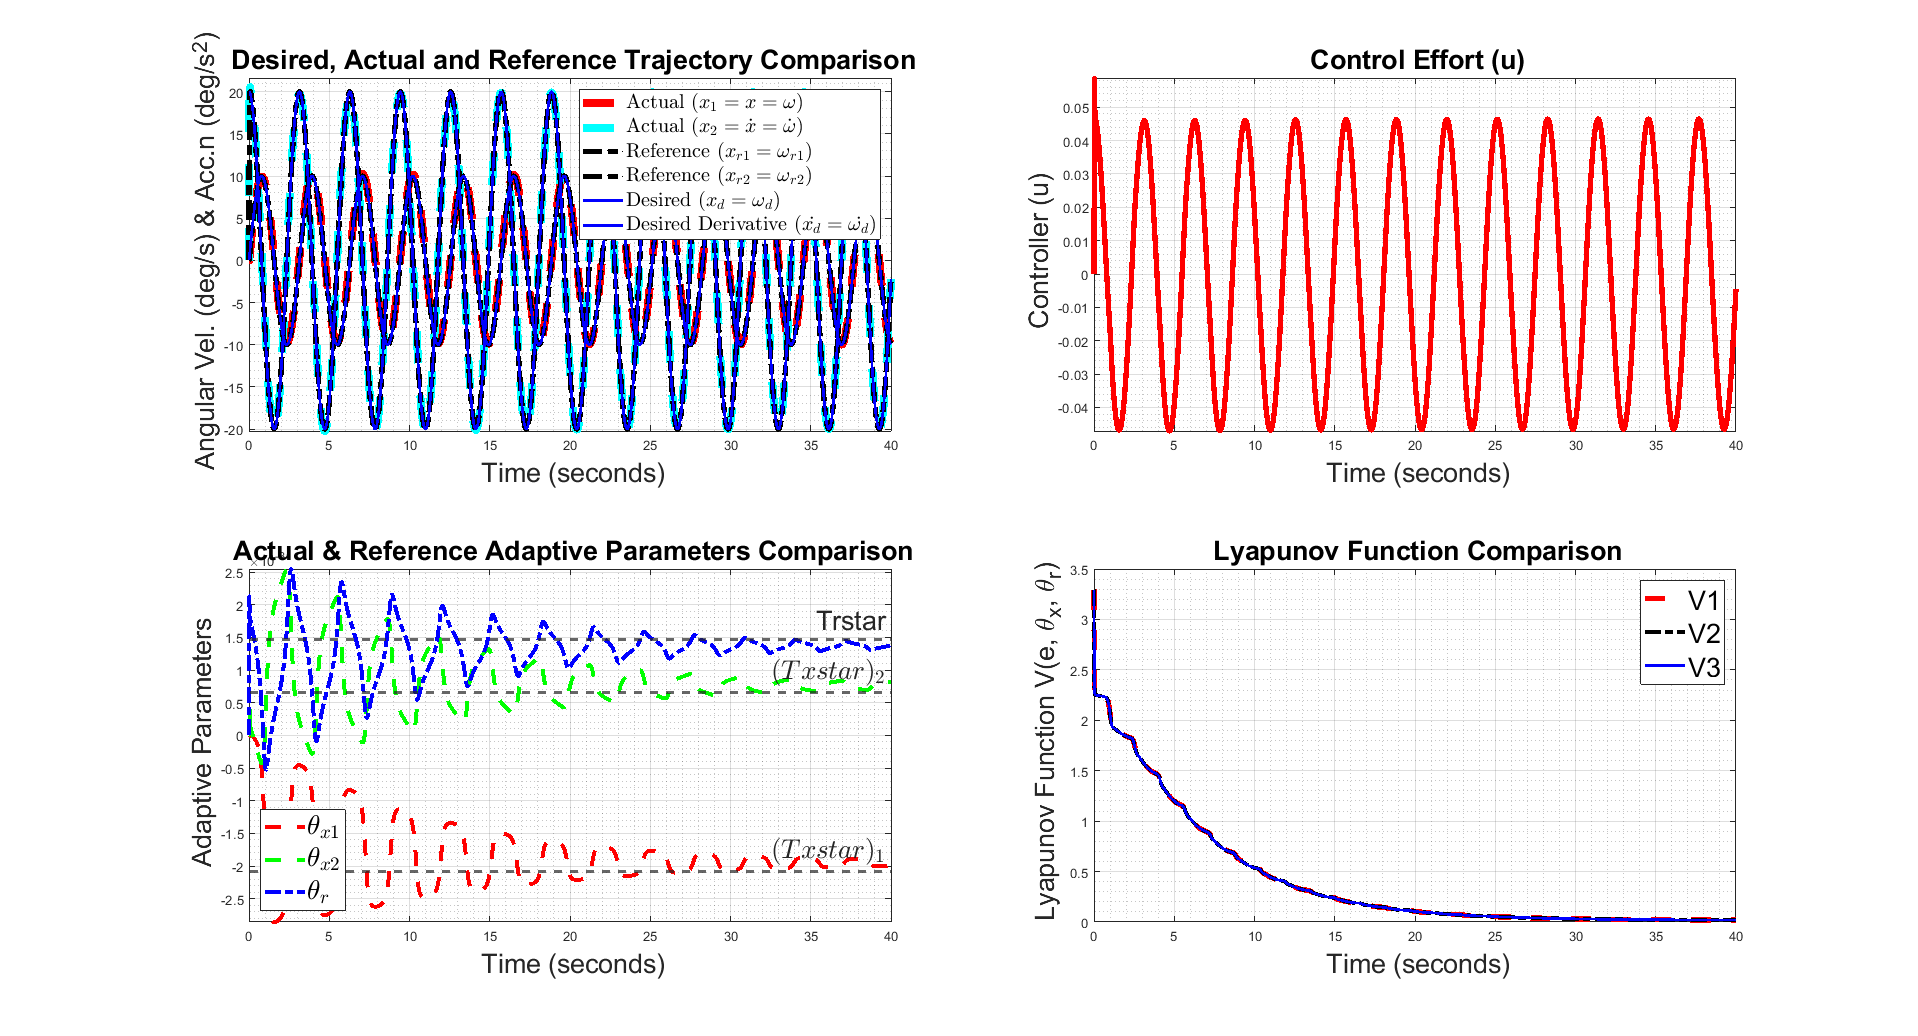


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%------ Desired, Reference and Actual Trajectory(Omega) -----%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

figure()
% subplot(1, 2, 1)
subplot(2,2,1)
plot(tout, x1, 'LineWidth', 6, 'LineStyle', '--', 'Color', 'r');    % For Full 2nd Order System
hold on
grid on
grid minor
axis tight
plot(tout, x2, 'LineWidth', 6, 'LineStyle', '--', 'Color', 'c');    % For Full 2nd Order System
plot(tout, xr1, 'LineWidth', 4, 'LineStyle', '-.', 'Color', 'k'); 
plot(tout, xr2, 'LineWidth', 4, 'LineStyle', '-.', 'Color', 'k'); 
plot(tout, xd, 'LineWidth', 2, 'Color', 'b');  
plot(tout, dxd, 'LineWidth', 2, 'Color', 'b');                      % For Full 2nd Order System
lgd = legend('Actual ($x_1= x =\omega$)', 'Actual ($x_2 =\dot{x}=\dot{\omega}$)', 'Reference ($x_{r1} = \omega_{r1}$)',...
             'Reference ($x_{r2} = \omega_{r2}$)', 'Desired ($x_d = \omega_d$)',...
             'Desired Derivative ($\dot{x_d} = \dot{\omega_d}$)', 'interpreter', 'latex'); % For Full 2nd Order System
lgd.FontSize = 15;
xlabel('\fontsize{20} Time (seconds)', 'interpreter', 'tex'); 
ylabel('\fontsize{20} Angular Vel. (deg/s) & Acc.n (deg/s^2)', 'interpreter', 'tex');  % For Full 2nd Order System
title('\fontsize{20} Desired, Actual and Reference Trajectory Comparison', 'interpreter', 'tex');
hold off
% % In order to maximize the figure window in Windows
% set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, 1, 0.96]);

%%%%%%%%%%%%%%%%%%%%
%------ Error -----%
%%%%%%%%%%%%%%%%%%%%

% subplot(1,2, 2)
% plot(tout, Error1, 'LineWidth', 6, 'LineStyle', '--', 'Color', 'r');        % For Full 2nd Order System
% hold on
% grid on
% grid minor
% axis tight
% plot(tout, Error2, 'LineWidth', 4, 'LineStyle', '--', 'Color', 'c');        % For Full 2nd Order System
% plot(tout, Error_ref1, 'LineWidth', 4, 'LineStyle', '-.', 'Color', 'k');    % For Full 2nd Order System
% plot(tout, Error_ref2, 'LineWidth', 4, 'LineStyle', '-.', 'Color', 'b');    % For Full 2nd Order System
% % xlim([0, max(t)]); 
% % ylim([-2 2]);
% lgd = legend('Error1 ($e_1 = x_1 - x_{r1}$)', 'Error2 ($e_2 = x_2 - x_{r2}$)',...
%     'Error reference 1 ($e_{r1} = x_{r1} - x_d$)', 'Error reference 2 ($e_{r2} = x_{r2} - x_d$)', 'interpreter', 'latex'); % For Full 2nd Order System
% lgd.FontSize = 15; lgd.Location = 'southeast';
% xlabel('\fontsize{20} Time (seconds)', 'interpreter', 'tex'); 
% ylabel('\fontsize{20} Error', 'interpreter', 'tex'); 
% title('\fontsize{20} Actual and Reference Error Comparison', 'interpreter', 'tex');
% hold off
% % In order to maximize the figure window in Windows
% set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, 1, 0.96]);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%------ Reference and Actual Adaptive Parameters -----%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Take care of the oscillation 

% figure()
% subplot(1,2, 1)
subplot(2,2, 3)
plot(tout, thx1, 'LineWidth', 3, 'LineStyle', '--', 'Color', 'r');      % For Full 2nd Order System
hold on
grid on
grid minor
axis tight
plot(tout, thx2, 'LineWidth', 3, 'LineStyle', '--', 'Color', 'g');      % For Full 2nd Order System
plot(tout,thr, 'LineWidth', 3, 'LineStyle', '-.', 'Color', 'b');
y1 = yline(Tx_star1,'--','$(Txstar)_1$', 'interpreter', 'latex','LineWidth',2);
y2 = yline(Tx_star2,'--','$(Txstar)_2$', 'interpreter', 'latex','LineWidth',2);
y3 = yline(Tr_star,'--','Trstar','LineWidth',2);
y1.FontSize = 20; y2.FontSize= y1.FontSize; y3.FontSize = y1.FontSize;
lgd = legend('$\theta_{x1}$', '$\theta_{x2}$', '$\theta_{r}$', 'interpreter', 'latex');
lgd.FontSize = 20; lgd.Location = 'southwest';
xlabel('\fontsize{20} Time (seconds)', 'interpreter', 'tex'); 
ylabel('\fontsize{20} Adaptive Parameters', 'interpreter', 'tex'); 
title('\fontsize{20} Actual & Reference Adaptive Parameters Comparison', 'interpreter', 'tex');
hold off
% % In order to maximize the figure window in Windows
% set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, 1, 0.96]);

% subplot(1,2, 2)
% plot(tout,dthx, 'LineWidth', 3, 'LineStyle', '-.', 'Color', 'k'); 
% hold on
% grid on
% grid minor
% axis tight
% plot(tout,dthr, 'LineWidth', 3, 'LineStyle', '-.', 'Color', 'c');
% % yline(10,'--','Max limit for u','LineWidth',2);
% % yline(-10,'--','Min limit for u','LineWidth',2);
% lgd = legend('$\dot{\theta_x}$', '$\dot{\theta_r}$', 'interpreter', 'latex');
% lgd.FontSize = 30; lgd.Location = 'southwest';
% xlabel('\fontsize{20} Time (seconds)', 'interpreter', 'tex'); 
% ylabel('\fontsize{20} Adaptive Parameters', 'interpreter', 'tex'); 
% title('\fontsize{20} Actual & Reference Adaptive Parameters Comparison', 'interpreter', 'tex');
% hold off
% % In order to maximize the figure window in Windows
% set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, 1, 0.96]);

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%------ Controller (u) -----%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% figure()
% subplot(1,2,1)
subplot(2,2,2)
plot(tout, u, 'LineWidth', 4, 'Color', 'r');      
hold on
grid on
grid minor
axis tight    
% yline(10,'--','Max limit for u','LineWidth',2);
% yline(-10,'--','Min limit for u','LineWidth',2);
% xlim([0, max(t)]); 
% ylim([-12 12]);
xlabel('\fontsize{20} Time (seconds)', 'interpreter', 'tex'); 
ylabel('\fontsize{20} Controller (u)', 'interpreter', 'tex'); 
title('\fontsize{20} Control Effort (u)', 'interpreter', 'tex');
hold off
% % In order to maximize the figure window in Windows
% set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, 1, 0.96]);

% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% %------ Lyapunov Function Comparison -----%
% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Lyapunov functions should be monotonically decreasing

% subplot(1,2,2)
subplot(2,2,4)
plot(tout, V1, 'LineWidth', 4, 'LineStyle', '--', 'Color', 'r'); 
hold on
grid on
grid minor
plot(tout, V2, 'LineWidth', 3, 'LineStyle', '-.', 'Color', 'k'); 
plot(tout, V3, 'LineWidth', 2, 'Color', 'b'); 
% ylim([-12 12]);
lgd = legend('V1', 'V2', 'V3', 'interpreter', 'tex');
lgd.FontSize = 20;
xlabel('\fontsize{20} Time (seconds)', 'interpreter', 'tex'); 
ylabel('\fontsize{20} Lyapunov Function V(e, \theta_x, \theta_r)', 'interpreter', 'tex'); 
title('\fontsize{20} Lyapunov Function Comparison', 'interpreter', 'tex');
hold off

% In order to maximize the figure window in Windows
set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, 1, 0.96]);

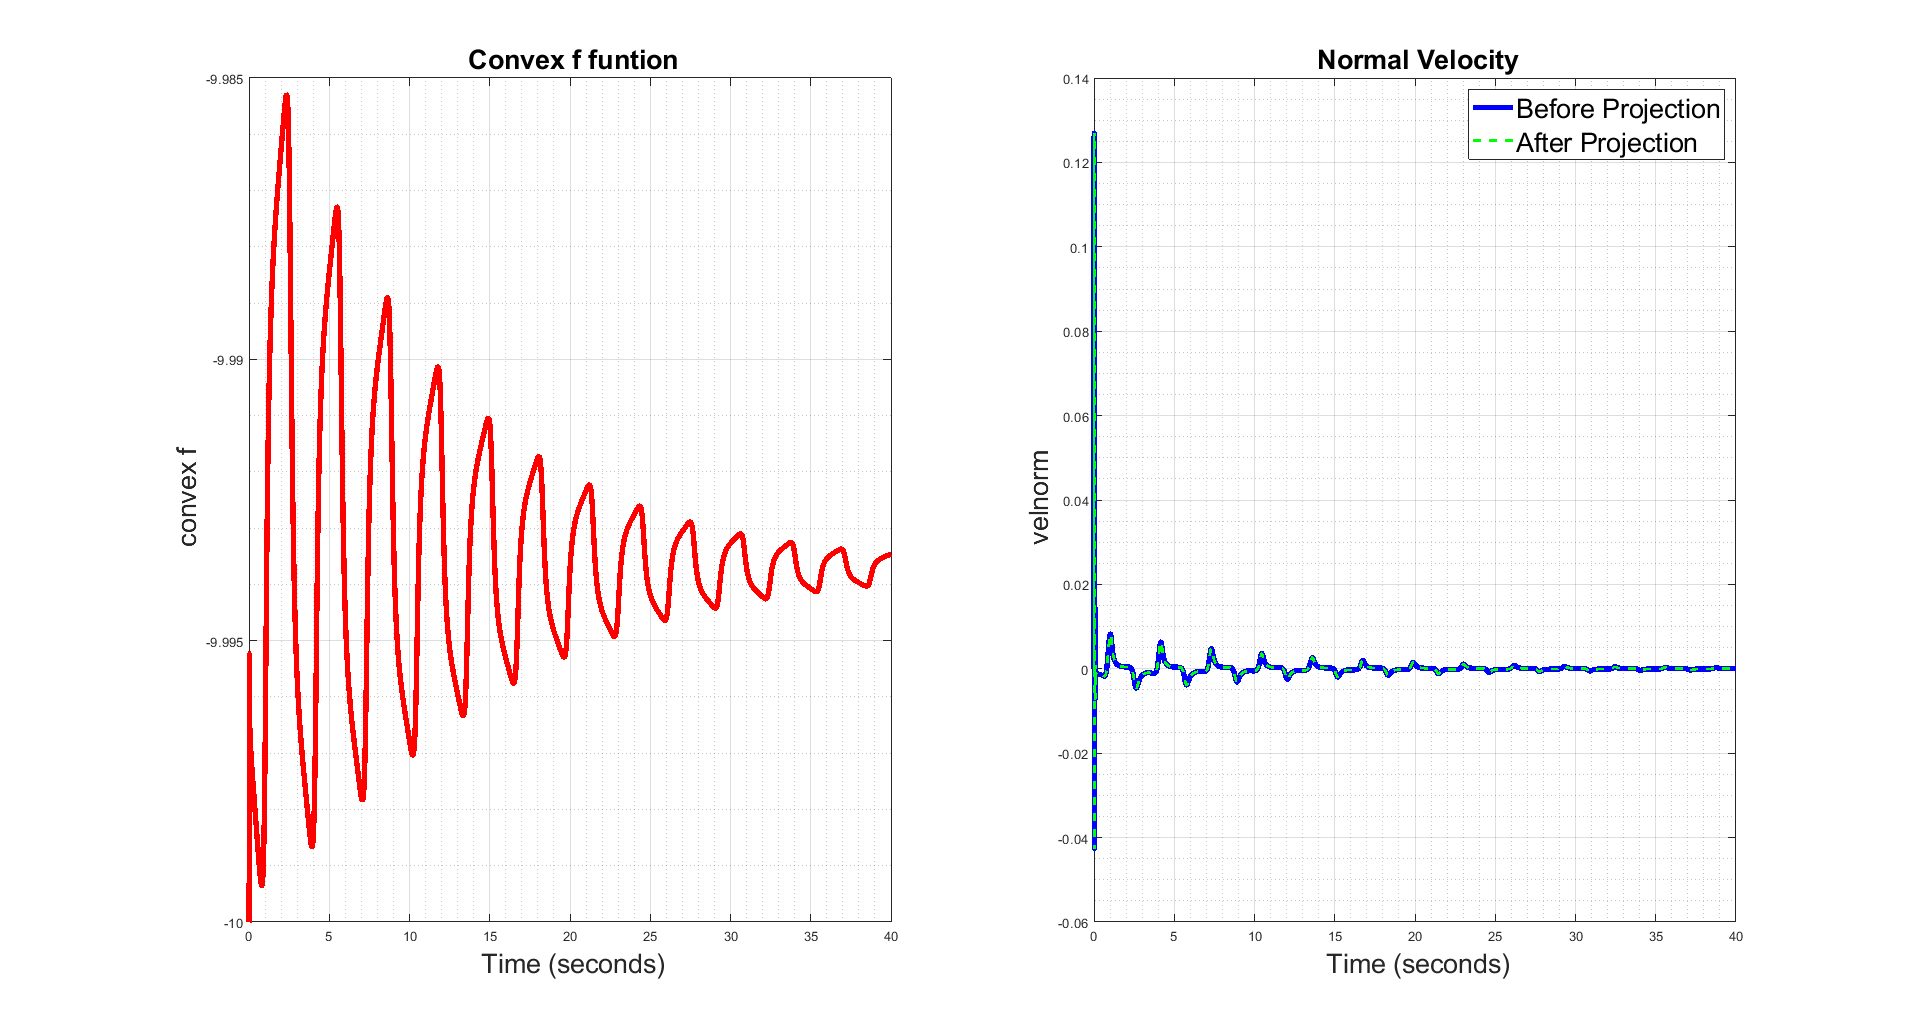

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%------ Projection Stuff -----%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

figure()
subplot(1,2,1)
plot(time_projection, convexF, 'LineWidth', 4, 'Color', 'r'); 
% plot(convexF);
hold on
grid on
grid minor
% ylim([-12 12]);
xlabel('\fontsize{20} Time (seconds)', 'interpreter', 'tex'); 
ylabel('\fontsize{20} convex f', 'interpreter', 'tex'); 
title('\fontsize{20} Convex f funtion', 'interpreter', 'tex');
hold off

% In order to maximize the figure window in Windows
set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, 1, 0.96]);

% figure()
subplot(1,2,2)
plot(time_projection, velnormal, 'LineWidth', 4, 'Color', 'b'); 
hold on
grid on
grid minor
plot(time_projection, velnormal2,'LineStyle', '--', 'LineWidth', 2, 'Color', 'g'); 
lgd = legend('Before Projection', 'After Projection', 'interpreter', 'tex');
lgd.FontSize = 20;
xlabel('\fontsize{20} Time (seconds)', 'interpreter', 'tex'); 
ylabel('\fontsize{20} velnorm', 'interpreter', 'tex'); 
title('\fontsize{20} Normal Velocity', 'interpreter', 'tex');
hold off


% In order to maximize the figure window in Windows
set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, 1, 0.96]);